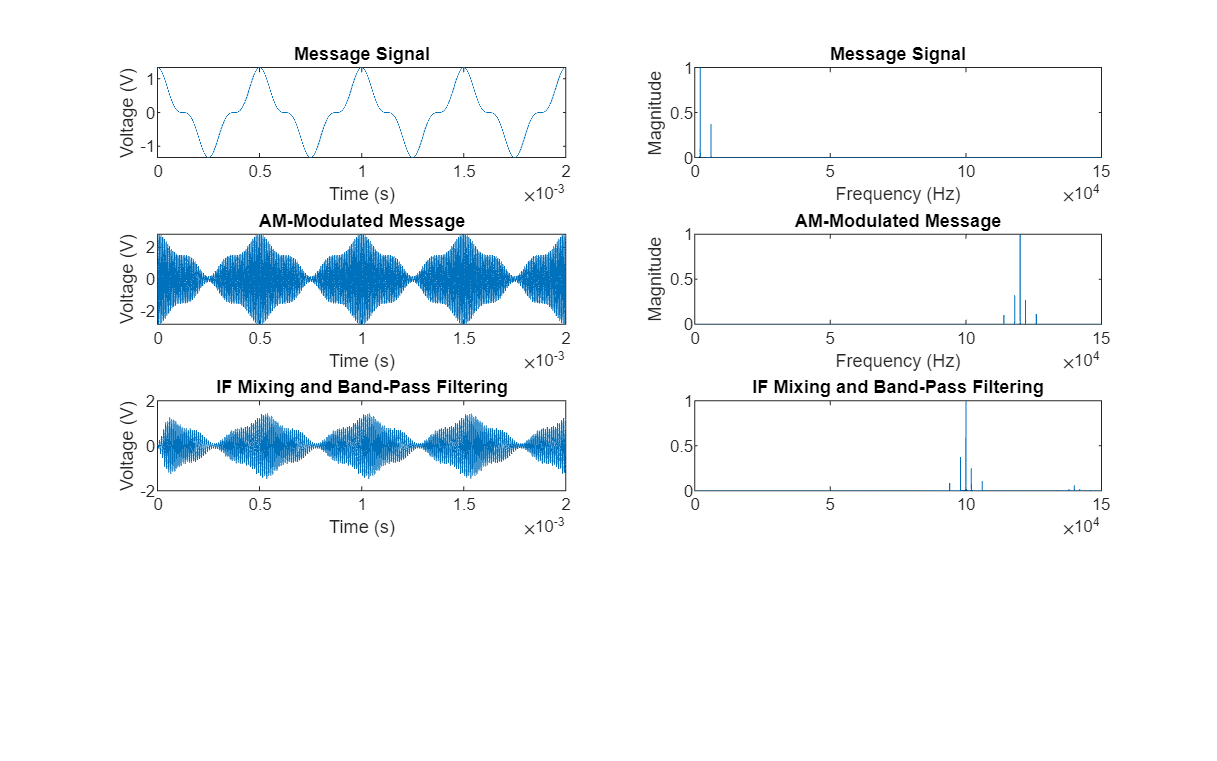

% Plots time and frequency-domain images of various stages of a
% superheterodyne receiver
clear; clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER-DEFINED VALUES %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%time domain constants
fs = 10^7; %sampling rate
max_t = 1/500; %highest time displayed
%frequency domain constants
nfft = 2^20; %fft samples
max_f = 150*10^3; %highest frequency displayed
%other constants
k = 10^3;
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% RUN-TIME PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts = 1/fs;
time_repeats = 100; %extra time scale for a more accurate FFT
%frequency axis scaling
fscale = fs/max_f; %scaling factor
if (fscale < 1)
 error('Your max. frequency is too high!')
end
%create time vector
t = 0:ts:time_repeats*max_t;
%%%%%%%%%%%%%%%%%%%%%%%%%
% SIGNAL GENERATION %
%%%%%%%%%%%%%%%%%%%%%%%%%
fc = 120*k;
fhet = 20*k;
fi = 100*k;
%generate AM
message = cos(2*pi*2*k*t) + 0.333*cos(2*pi*6*k*t);
carrier = cos(2*pi*fc*t);
am = carrier .* (message+1.5);
het_oscillator = cos(2*pi*fhet*t);
%generate other AM waves to simulate interference by neighboring AM

%stations (optional simulation)
am2 = cos(2*pi*40*k*t) .* (cos(2*pi*4.5*k*t)+1.5);
am3 = cos(2*pi*100*k*t) .* (cos(2*pi*k*t)+1.5);
%am = am + am2 + am3;
%apply IF mixer
mixer = am .* het_oscillator;
%apply band-pass filter
order = 4; %must be even
BW = 8*k; %filter bandwidth, must be at least the highest freq. component in the message
fc1 = 2*(fi-BW)/fs; fc2 = 2*(fi+BW)/fs; %normalized frequencies
[b,a] = butter(order/2, [fc1, fc2]);
bpf = filter(b, a, mixer);
%apply envelope detector
order = 4;
fc1 = 10*k;
env = abs(bpf);
[b,a] = butter(order/2, 2*(fc1/fs));
demod = filter(b, a, env);
%create frequency-domain vectors
f = (0:round(nfft/fscale)-1); %frequency vector
f = f * (fs/nfft);
x_message = abs(fft(message, nfft));
x_message = x_message(1:round(nfft/fscale));
x_message = x_message / max(x_message);
x_am = abs(fft(am, nfft));
x_am = x_am(1:round(nfft/fscale));
x_am = x_am / max(x_am);
x_bpf = abs(fft(bpf, nfft));
x_bpf = x_bpf(1:round(nfft/fscale));
x_bpf = x_bpf / max(x_bpf);
x_demod = abs(fft(demod, nfft));
x_demod = x_demod(1:round(nfft/fscale));
x_demod = x_demod / max(x_demod);
%time-domain scaling
t = t(1:(size(t,2)-1) / time_repeats); %restrict vector size to max_t
message = message(1:(size(message,2)-1) / time_repeats);
am = am(1:(size(am,2)-1) / time_repeats);
bpf = bpf(1:(size(bpf,2)-1) / time_repeats);
demod = demod(1:(size(demod,2)-1) / time_repeats);
%%%%%%%%%%%%%%%
% OUTPUT %
%%%%%%%%%%%%%%%
%figure;
hfig = figure('name','AM Demodulation with a superheterodyne Receiver','units','normalized','outerposition',[0 0 1 1]);
subplot(4,2,1)

plot(t, message)
title('Message Signal')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,2)
plot(f, x_message)
title('Message Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,3)
plot(t, am)
title('AM-Modulated Message')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,4)
plot(f, x_am)
title('AM-Modulated Message')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,5)
plot(t, bpf)
title('IF Mixing and Band-Pass Filtering')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,6)
plot(f, x_bpf)
title('IF Mixing and Band-Pass Filtering')

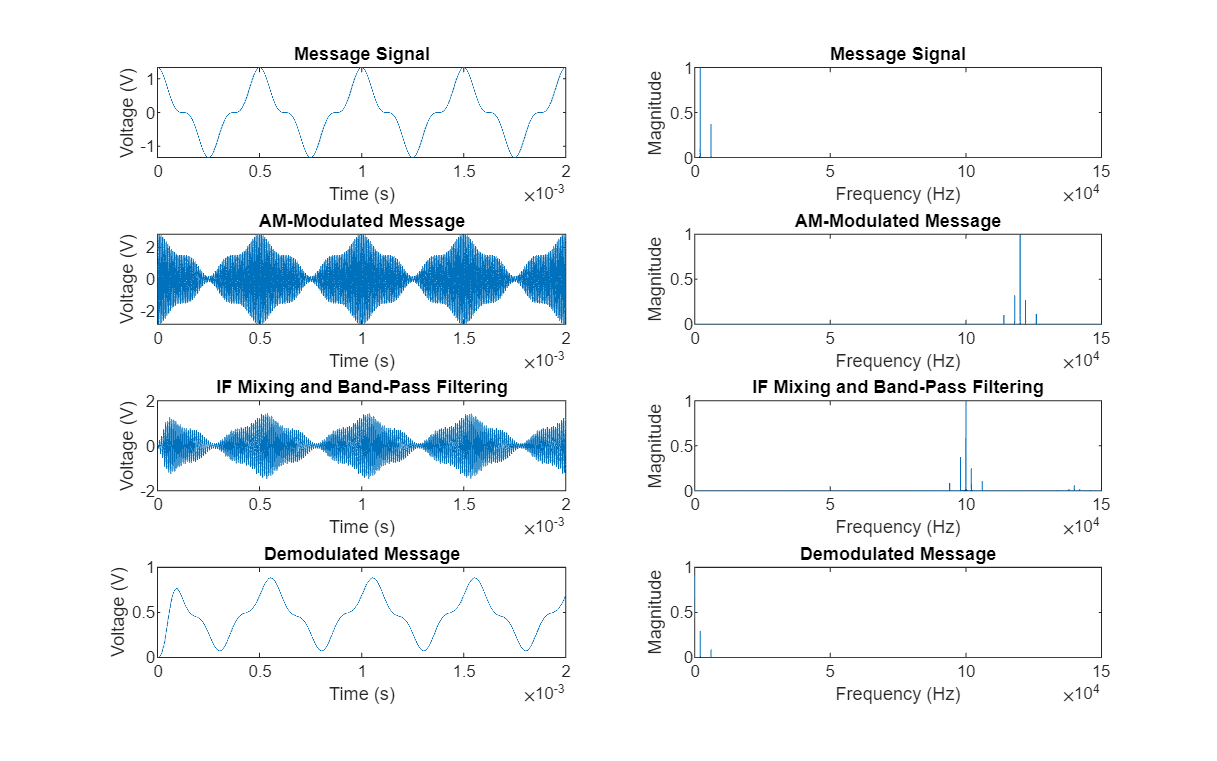

% Plots time and frequency-domain images of various stages of a
% superheterodyne receiver
clear; clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% USER-DEFINED VALUES %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%time domain constants
fs = 10^7; %sampling rate
max_t = 1/500; %highest time displayed
%frequency domain constants
nfft = 2^20; %fft samples
max_f = 150*10^3; %highest frequency displayed
%other constants
k = 10^3;
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% RUN-TIME PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts = 1/fs;

time_repeats = 100; %extra time scale for a more accurate FFT
%frequency axis scaling
fscale = fs/max_f; %scaling factor
if (fscale < 1)
 error('Your max. frequency is too high!')
end
%create time vector
t = 0:ts:time_repeats*max_t;
%%%%%%%%%%%%%%%%%%%%%%%%%
% SIGNAL GENERATION %
%%%%%%%%%%%%%%%%%%%%%%%%%
fc = 120*k;
fhet = 20*k;
fi = 100*k;
%generate AM
message = cos(2*pi*2*k*t) + 0.333*cos(2*pi*6*k*t);
carrier = cos(2*pi*fc*t);
am = carrier .* (message+1.5);
het_oscillator = cos(2*pi*fhet*t);
%generate other AM waves to simulate interference by neighboring AM
%stations (optional simulation)
am2 = cos(2*pi*40*k*t) .* (cos(2*pi*4.5*k*t)+1.5);
am3 = cos(2*pi*100*k*t) .* (cos(2*pi*k*t)+1.5);
%am = am + am2 + am3;
%apply IF mixer
mixer = am .* het_oscillator;
%apply band-pass filter
order = 4; %must be even
BW = 8*k; %filter bandwidth, must be at least the highest freq. component in the message
fc1 = 2*(fi-BW)/fs; fc2 = 2*(fi+BW)/fs; %normalized frequencies
[b,a] = butter(order/2, [fc1, fc2]);
bpf = filter(b, a, mixer);
%apply envelope detector
order = 4;
fc1 = 10*k;
env = abs(bpf);
[b,a] = butter(order/2, 2*(fc1/fs));
demod = filter(b, a, env);
%create frequency-domain vectors
f = (0:round(nfft/fscale)-1); %frequency vector
f = f * (fs/nfft);
x_message = abs(fft(message, nfft));
x_message = x_message(1:round(nfft/fscale));
x_message = x_message / max(x_message);
x_am = abs(fft(am, nfft));

x_am = x_am(1:round(nfft/fscale));
x_am = x_am / max(x_am);
x_bpf = abs(fft(bpf, nfft));
x_bpf = x_bpf(1:round(nfft/fscale));
x_bpf = x_bpf / max(x_bpf);
x_demod = abs(fft(demod, nfft));
x_demod = x_demod(1:round(nfft/fscale));
x_demod = x_demod / max(x_demod);
%time-domain scaling
t = t(1:(size(t,2)-1) / time_repeats); %restrict vector size to max_t
message = message(1:(size(message,2)-1) / time_repeats);
am = am(1:(size(am,2)-1) / time_repeats);
bpf = bpf(1:(size(bpf,2)-1) / time_repeats);
demod = demod(1:(size(demod,2)-1) / time_repeats);
%%%%%%%%%%%%%%%
% OUTPUT %
%%%%%%%%%%%%%%%
%figure;
hfig = figure('name','AM Demodulation with a Superheterodyne Receiver','units','normalized','outerposition',[0 0 1 1]);
subplot(4,2,1)
plot(t, message)
title('Message Signal')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,2)
plot(f, x_message)
title('Message Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,3)
plot(t, am)
title('AM-Modulated Message')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,4)
plot(f, x_am)
title('AM-Modulated Message')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,5)
plot(t, bpf)
title('IF Mixing and Band-Pass Filtering')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,6)
plot(f, x_bpf)

title('IF Mixing and Band-Pass Filtering')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,7)
plot(t, demod)
title('Demodulated Message')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,8)
plot(f, x_demod)
title('Demodulated Message')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(4,2,7)
plot(t, demod)
title('Demodulated Message')
xlabel('Time (s)')
ylabel('Voltage (V)')
subplot(4,2,8)
plot(f, x_demod)
title('Demodulated Message')
xlabel('Frequency (Hz)')
ylabel('Magnitude')